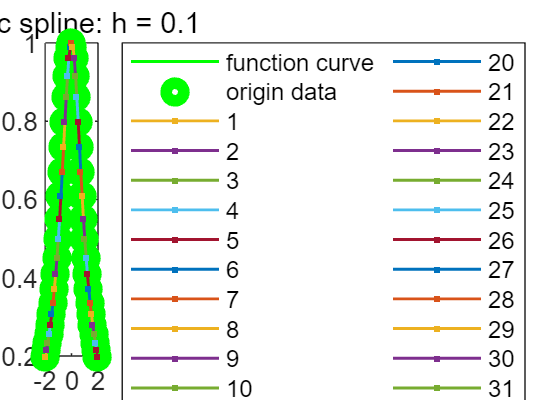

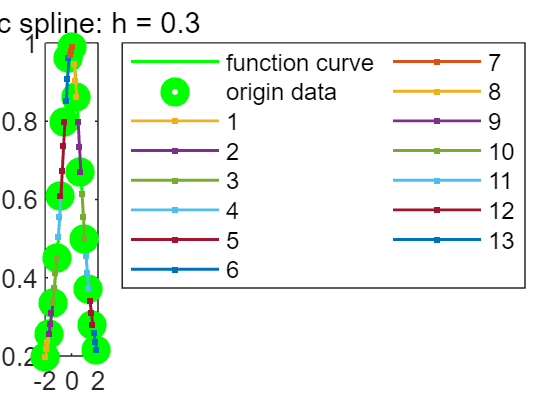

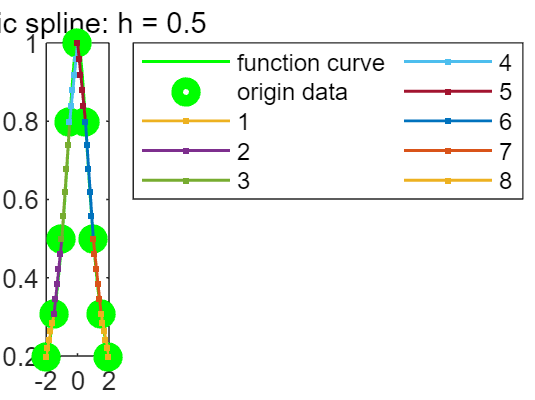

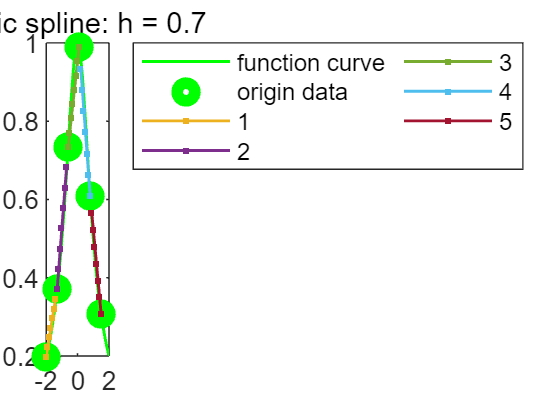

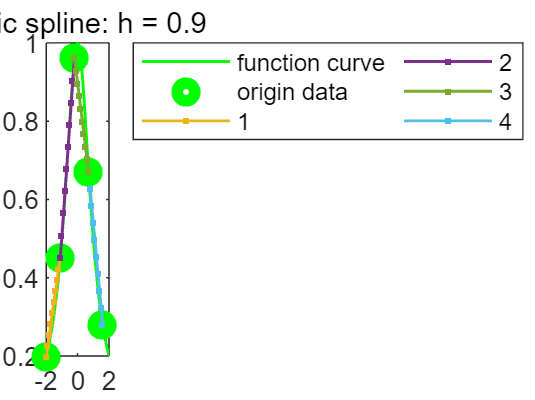

clc;clear;close all;
x = -2:0.1:2;
boun_set = [1, 0, 0];
h = 0.1:0.2:1;

for iStep = 1:1:length(h)
    x0s = -2:h(iStep):2;
    fx0s = (1 + x0s.^2).^(-1);
    figure;
    plot(x, (1 + x.^2).^(-1), '-', 'color', 'g', 'LineWidth', 1, 'DisplayName', 'function curve');
    polynomial_interpolation(x0s, fx0s, x, 2, boun_set);
    title_str = sprintf('cubic spline: h = %.1f', h(iStep));
    title(title_str);
end